clear all; close all;
%rav = ravdess_database();
emdb = berlin_emotional_database();
%hum = humaine();

%rav_emotions = rav.Labels;
emdb_emotions = emdb.Labels;
num_emotions = number_emotions(emdb_emotions);

%rav.Labels = 1:length(rav.Files);
emdb.Labels = 1:length(emdb.Files);
%hum.Labels = 1:length(hum.Files);

%rav_info = audioinfo(rav.Files{1,1});
fs = 8000;

new_emdb = transform (emdb, @(x,info) resample_datastore(x, info, ...
                                fs), 'IncludeInfo', true);
%new_hum = transform (emdb, @(x,info) resample_datastore(x, info, ...
%                                fs), 'IncludeInfo', true);


%ads = combine(rav, new_emdb, new_hum);
%shAds = shuffle(ads);
%subAds1 = partition(shAds,3,1);
%subAds2 = partition(shAds,3,2);
%subAds3 = partition(shAds,3,3);

% extracts a vector of features and returns their names and idxs 
[features, feature_idxs, feature_names] = extract_features(new_emdb, fs);
[szr, szc] = size(features);
[~, num_of_features] = size(features{1,1});



% min = 10e4;
% for ii = 1:szc
%     [si,~] = size(features{1,ii});
%     if si < min
%         min = si;
%     end
% end

% extracts stats by the vector stats2extract and assigns an emotion to each
% speech segment
stats2extract = 1:18;
num_of_stats = numel(stats2extract);
[stats, stat_names] = extract_stats(features, stats2extract, num_emotions, num_of_features);



% fz = 1;
% sp = zeros(szr,min*col+1);
% for e = 1:szc
%     s = size(features{1,e});
%     f(fz:fz+s(1)-1,1:s(2)) = features{1,e};
%     f(fz:fz+s(1)-1, s(2)+1) = num_emotions(e);
%     conc = f(fz:fz+min-1, 1:s(2));
%     sp(e,1:end-1) = conc(:)';
%     sp(e,end) = num_emotions(e);
%     
%     fz = fz + s(1);
% end

% filters out the nan and inf values
stats = filter_nan_inf(stats);

% calculates the relieff algorithm and the returns the weights and idxs  
k = 2;
[weights, idxs] = relieff_weights(stats, emdb_emotions, k);

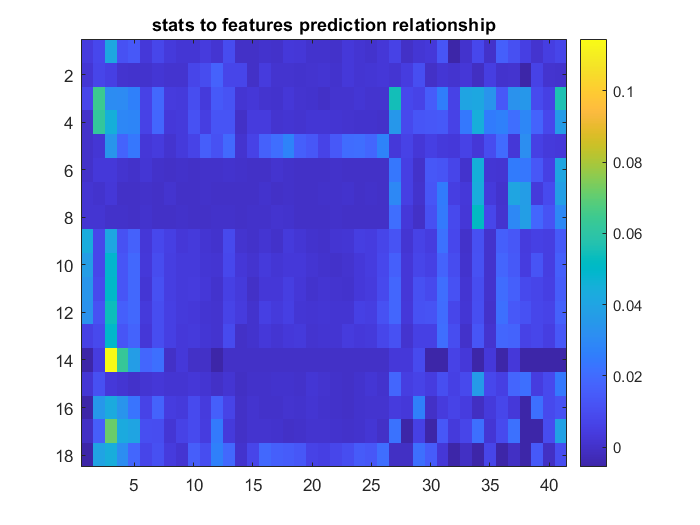

% creates a weight matrix and draws it using imagesc with weights denoted
% by a color bar
weight_matrix = create_weight_matrix(weights, num_of_features, num_of_stats);

imagesc(weight_matrix);
colorbar;
title("stats to features prediction relationship");

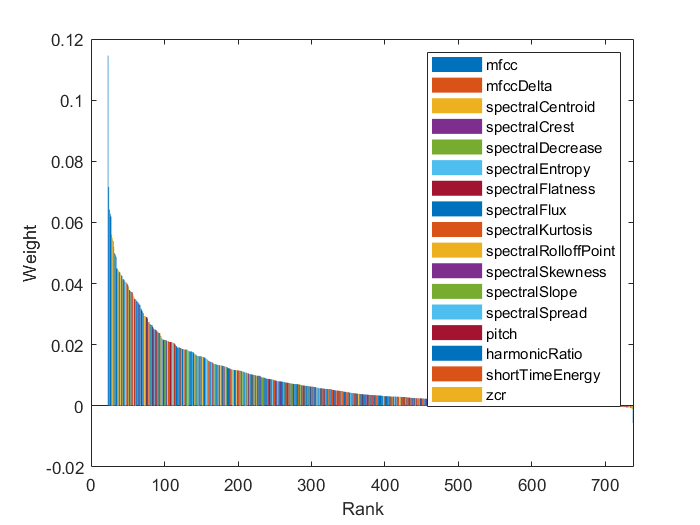

% creates a sorted weight bar graph that illustrates the rank of each stat
% and feature in classification  
sorted_weights_bar(weight_matrix, feature_idxs, feature_names);

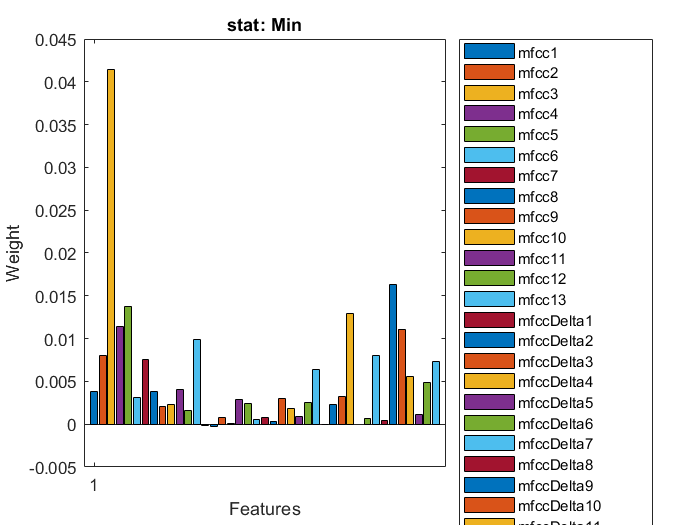

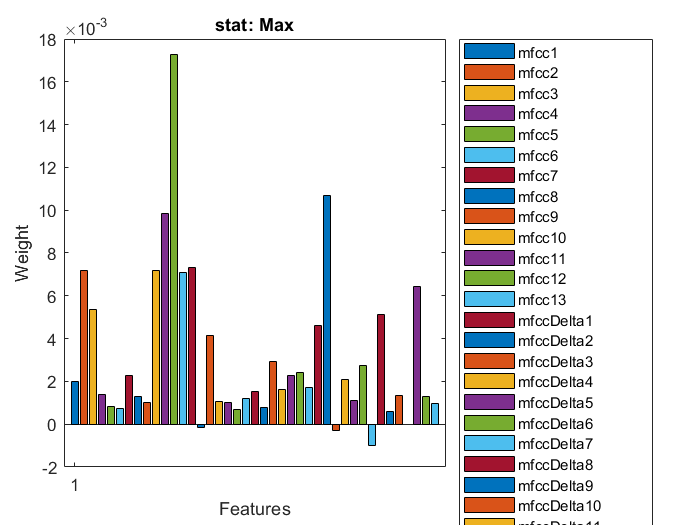

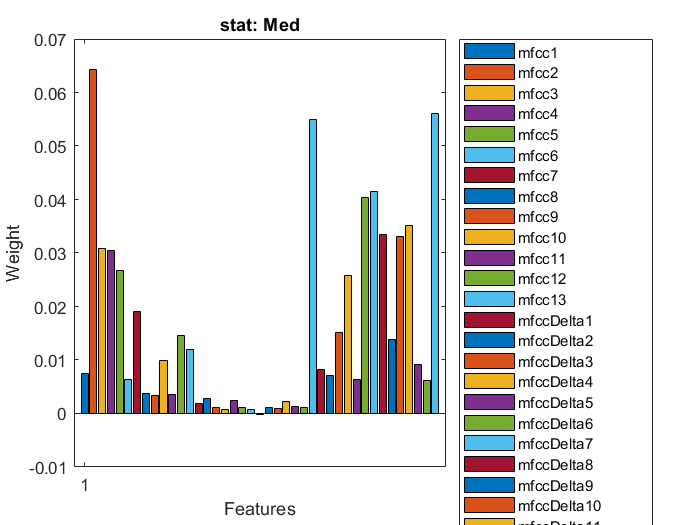

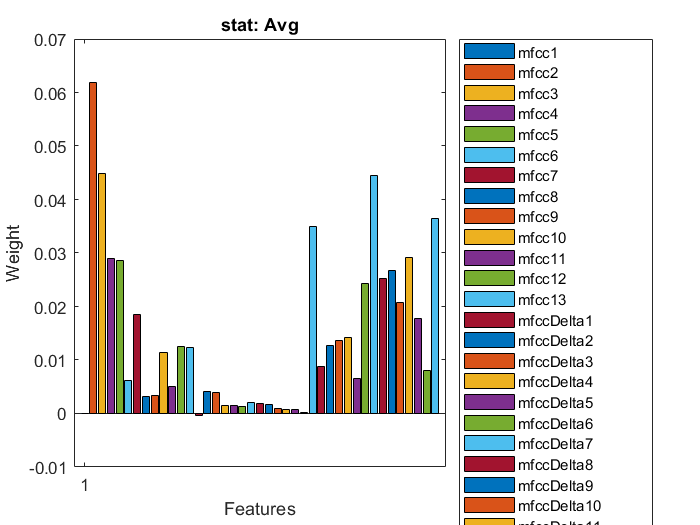

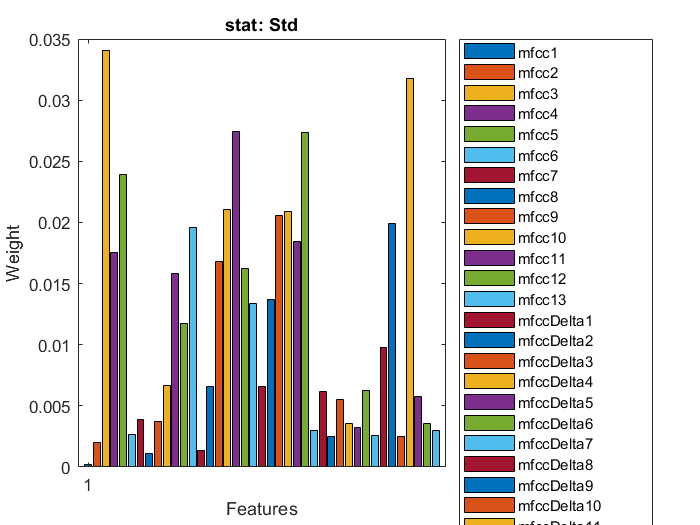

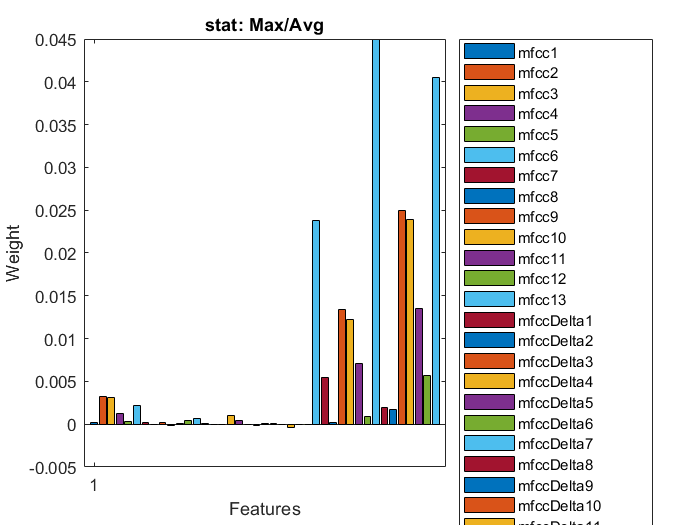

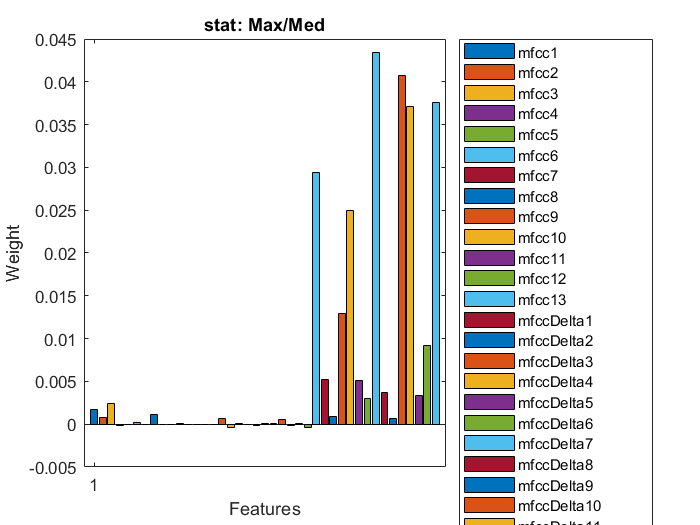

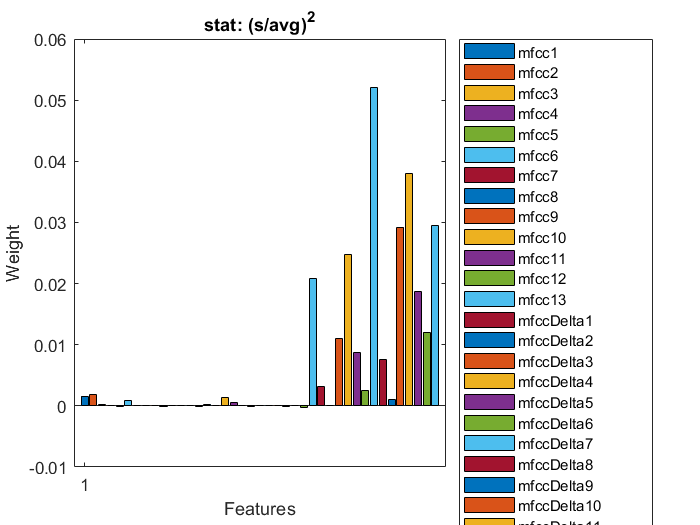

% creates sub bar graphs to zoom in on each stat independently
sub = sub_names(feature_names, feature_idxs, num_of_features);
sub_weight_bars(weight_matrix, sub, stat_names);


% deletes the stat, feature combinations that are below the threshold value
optimum_stats = weight_thr(stats, weight_matrix, 0.005);

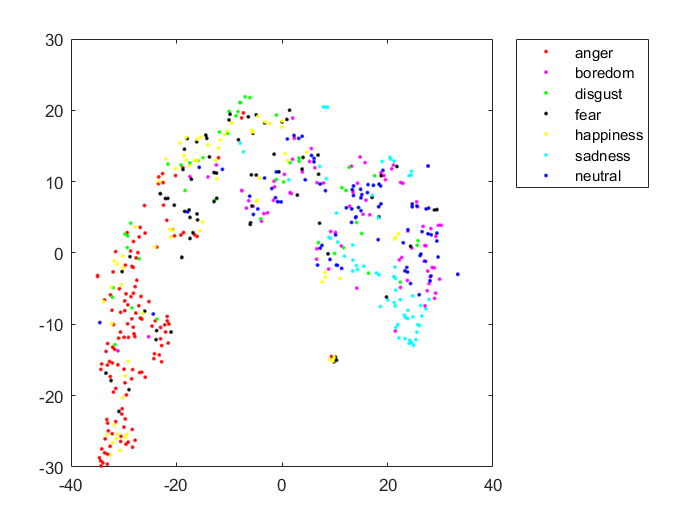


% plots the scattering of emotion points in 2D space using t-sne
labels = {'anger', 'boredom', 'disgust', 'fear', 'happiness', 'sadness','neutral'};
exaggeration = 10;
perplexity = 20;
plot_tsne(optimum_stats, labels, exaggeration, perplexity);